# Unsupervised Learning In-Class Practice: Answer Key

## Loading and examining the data

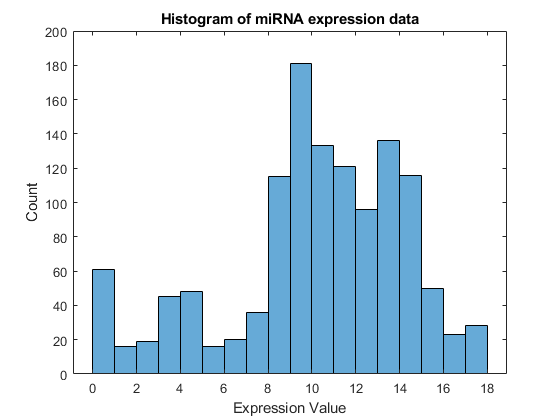

% Load the dataset
miRNA = readtable('miRNA_data.xlsx');
% Create a variable for patient IDs
patient_ID = miRNA.Patient_ID;
% Create a variable for patient health status
health_stat = miRNA.Health_Status; 
% Create a variable for gene names
genes = miRNA.Properties.VariableNames(3:end);
% Create a variable for gene expression data
miRNA_data = table2array(miRNA(:,3:end));

% Histogram of expression data
histogram(miRNA_data)
xlabel('Expression Value'); ylabel('Count')
title('Histogram of miRNA expression data')

Answer: The data is left-skewed. 

## Determining optimal k value using KMC

% Create a vector of k values ranging from 2 to 10
k_values = 2:10;

% For-loop to calculate the silhouette statistic for different k values
n = length(k_values);       % number of k values
s_statistic = zeros(n,1);   % variable to store silhouette statistic values
for i = 1:n
    % Use the kmeans function to cluster patients into k clusters
    [idx,~] = kmeans(miRNA_data,k_values(i));
    % Use the silhouette function to calculate silhouette values
    s = silhouette(miRNA_data,idx);
    % Calculate a weight value proportional to positive silhouette values
    weight = sum(s > 0)/length(s);
    % Calculate the silhouette statistic by multiplying the weight with the
    % mean of silhouette values and store this to s_statistic
    s_statistic(i) = weight*mean(s);
end
max(s_statistic)

ans = 0.5539

k = find(s_statistic==max(s_statistic))+1

k = 2

Answer: The max silhouette statistic is equal to 0.5539, and this corresponds with k = 2.

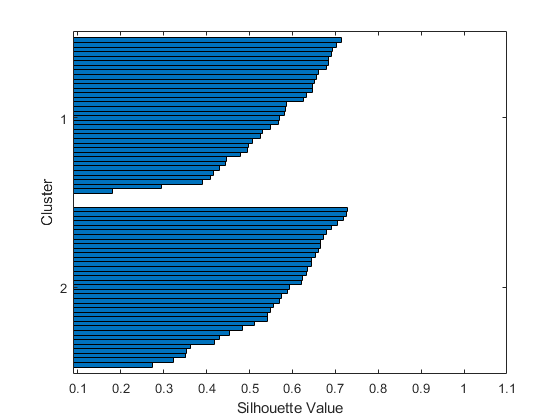

% Silhouette plot based on best k value
[idx,~] = kmeans(miRNA_data,k);
silhouette(miRNA_data,idx)

Answer: No negative values are present, but a negative silhouette value would imply that its associated observation was not well-placed into its assigned cluster. 

cluster_1 = health_stat(idx == 1)

cluster_1 = 35×1 cell array
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'diseased'}
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }
    {'healthy' }


cluster_2 = health_stat(idx == 2)

cluster_2 = 35×1 cell array
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}
    {'diseased'}


Answer: The patients cluster based on health status (for the most part).

## Visualizing data in lower dimension using PCA

% Apply PCA to the gene expression data (use patient health status for labeling)
mapcaplot(miRNA_data,health_stat)

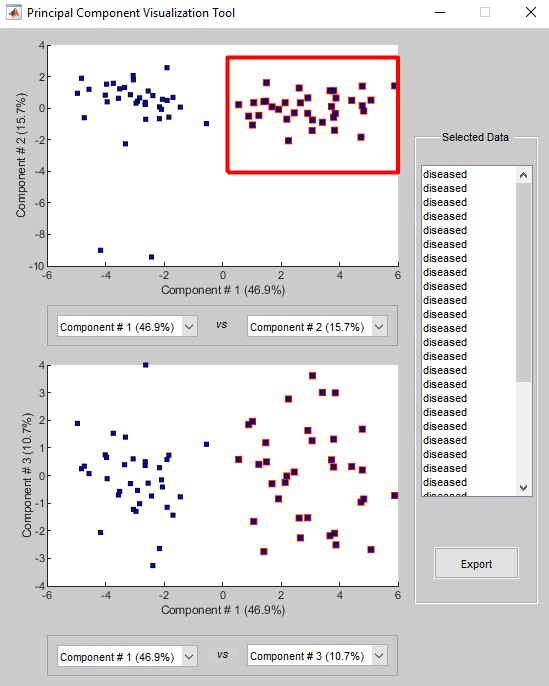

Answer: There seems to be two distinct clusters with two outliers. PC1 and PC2 account for 62.6% of the variance.

## Identifying disease using HC

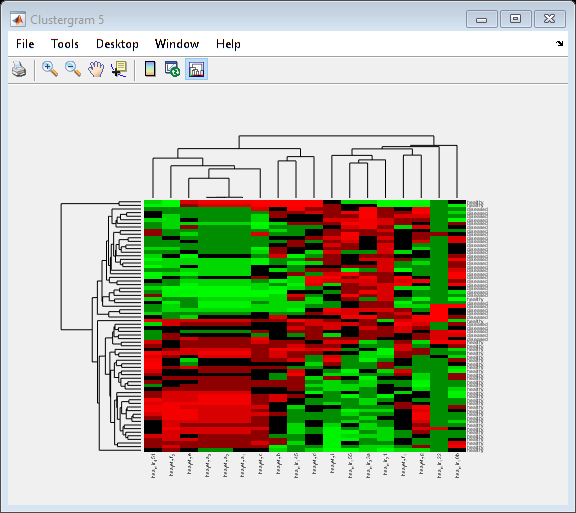

% Create clustergram (label rows, label columns, and standardize by
% columns)
miRNA_cg = clustergram(miRNA_data,...
    'RowLabels',health_stat,...
    'ColumnLabels',genes,...
    'Standardize','column');

Answer: It seems that the outliers were picked out at the edges, but the two clusters we've seen before are not clearly separated. 

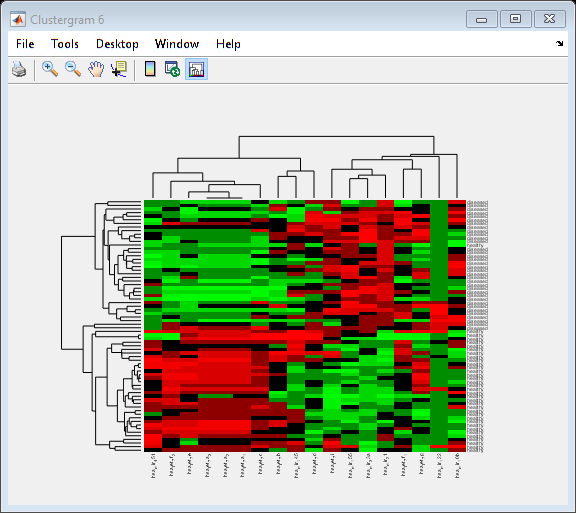

% Clustergram with redbluecmap
miRNA_cg_corr_rbc = clustergram(miRNA_data,...
    'RowLabels',health_stat,...
    'ColumnLabels',genes,...
    'Standardize','column',...
    'RowPDist','correlation',...
    'ColumnPDist','correlation');

Answer: As opposed to before, this clustergram better separates patients according to their health status. This matches closer to our previous results from KMC and PCA. 

Answer: Some signature miRNAs might be miR-451, *Let*-7, miR-155, miR-33, and miR-21. Refer to associated disease in signature miRNA table for potential disease that could be represented. 